# **DSP HW6**

**By: 106061151 劉安得**

## **1. (a)**


$$\begin{array}{l}
\frac{1}{N}\sum_{k=0}^{N-1} X\left\lbrack {<-k>}_N \right\rbrack W_N^{\mathrm{kn}} \\
=\frac{1}{N}X\left\lbrack 0\right\rbrack W_N^{-0n} +\frac{1}{N}\sum_{k=1}^{N-1} X\left\lbrack -k+N\right\rbrack W_N^{\mathrm{kn}} \\
=\frac{1}{N}X\left\lbrack 0\right\rbrack W_N^{-0n} +\frac{1}{N}\sum_{k^{\prime } =1}^{N-1} X\left\lbrack k^{\prime } \right\rbrack W_N^{\left(N-k^{\prime } \right)n} \\
=\frac{1}{N}X\left\lbrack 0\right\rbrack W_N^{-0n} +\frac{1}{N}\sum_{k^{\prime } =1}^{N-1} X\left\lbrack k^{\prime } \right\rbrack W_N^{-k^{\prime } n} W_N^{\mathrm{Nn}} \\
=\frac{1}{N}X\left\lbrack 0\right\rbrack W_N^{-0n} +\frac{1}{N}\sum_{k^{\prime } =1}^{N-1} X\left\lbrack k^{\prime } \right\rbrack W_N^{-k^{\prime } n} \\
=\frac{1}{N}\sum_{k=0}^{N-1} X\left\lbrack k\right\rbrack W_N^{-\mathrm{kn}} =x\left\lbrack n\right\rbrack 
\end{array}$$


## **1. (b)**

%Prob. 1(b)
x = [1, 2, 3, 4, 5, 6, 7, 8];
N = 8;
X = fft(x);
x_idft = IDFT(X, N);
x_idft

x_idft =      1     2     3     4     5     6     7     8


## **2. (b)**

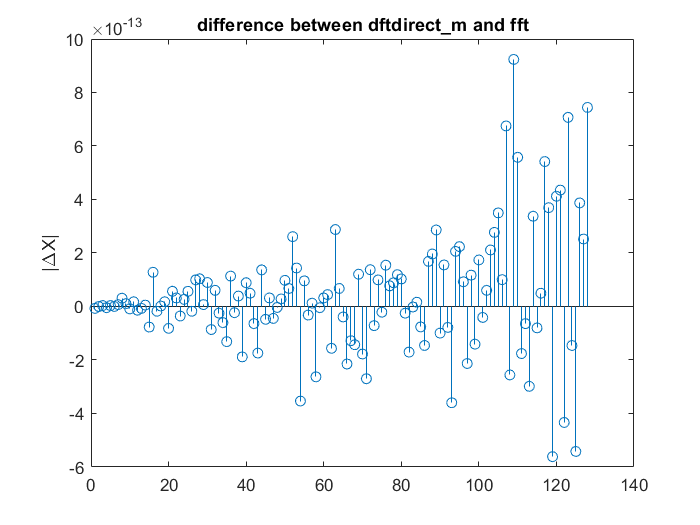

%Prob. 2(b)
N = 128;
x = randn(1,N) + 1j*randn(1,N);
W = dft_matrix(N);
X_dftdirect = dftdirect_m(x, W);
X_fft = fft(x);
dX = abs(X_dftdirect)-abs(X_fft);

figure
stem(dX)
title('difference between dftdirect\_m and fft')
ylabel('|\DeltaX|')

the difference between dftdirect_m and fft is smaller than 10^-12

N = 128;
x = randn(1,N) + 1j*randn(1,N);
W1 = dft_matrix(N);

disp("N = 128, dftdirect")

N = 128, dftdirect


tic
dftdirect(x);
toc

Elapsed time is 0.029640 seconds.



disp("N = 128, dftdirect_m")

N = 128, dftdirect_m


tic
dftdirect_m(x, W1);
toc

Elapsed time is 0.006887 seconds.



N = 256;
x = randn(1,N) + 1j*randn(1,N);
W2 = dft_matrix(N);

disp("N = 256, dftdirect")

N = 256, dftdirect


tic
dftdirect(x);
toc

Elapsed time is 0.027076 seconds.



disp("N = 256, dftdirect_m")

N = 256, dftdirect_m


tic
dftdirect_m(x, W2);
toc

Elapsed time is 0.011815 seconds.



N = 512;
x = randn(1,N) + 1j*randn(1,N);
W3 = dft_matrix(N);

disp("N = 512, dftdirect")

N = 512, dftdirect


tic
dftdirect(x);
toc

Elapsed time is 0.109446 seconds.



disp("N = 512, dftdirect_m")

N = 512, dftdirect_m


tic
dftdirect_m(x, W3);
toc

Elapsed time is 0.020008 seconds.



N = 1024;
x = randn(1,N) + 1j*randn(1,N);
W4 = dft_matrix(N);

disp("N = 1024, dftdirect")

N = 1024, dftdirect


tic
dftdirect(x);
toc

Elapsed time is 1.080772 seconds.



disp("N = 1024, dftdirect_m")

N = 1024, dftdirect_m


tic
dftdirect_m(x, W4);
toc

Elapsed time is 0.085574 seconds.


## 2. (c)

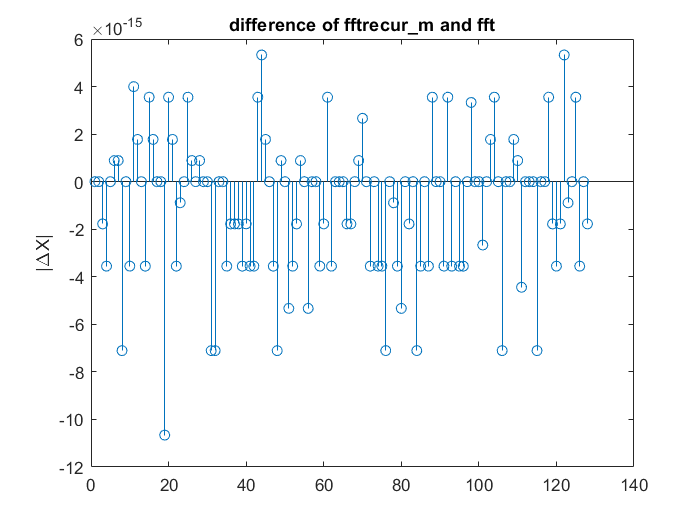

%Prob. 2(c)
N = 128;
x = randn(1,N) + 1j*randn(1,N);
W = dft_matrix(N);
X_fftrecur = fftrecur_m(x, W);
X_fft = fft(x);
dX = abs(X_fftrecur')-abs(X_fft);

figure
stem(dX)
title('difference of fftrecur\_m and fft')
ylabel('|\DeltaX|')

the difference between dftdirect_m and fft is smaller than 10^-14

N = 128;
x = randn(1,N) + 1j*randn(1,N);
W1 = dft_matrix(N);

disp("N = 128, fftrecur")

N = 128, fftrecur


tic
fftrecur(x);
toc

Elapsed time is 0.015877 seconds.



disp("N = 128, fftrecur_m")

N = 128, fftrecur_m


tic
fftrecur_m(x, W1);
toc

Elapsed time is 0.004685 seconds.



N = 256;
x = randn(1,N) + 1j*randn(1,N);
W2 = dft_matrix(N);

disp("N = 256, fftrecur")

N = 256, fftrecur


tic
fftrecur(x);
toc

Elapsed time is 0.007076 seconds.



disp("N = 256, fftrecur_m")

N = 256, fftrecur_m


tic
fftrecur_m(x, W2);
toc

Elapsed time is 0.006619 seconds.



N = 512;
x = randn(1,N) + 1j*randn(1,N);
W3 = dft_matrix(N);

disp("N = 512, fftrecur")

N = 512, fftrecur


tic
fftrecur(x);
toc

Elapsed time is 0.008425 seconds.



disp("N = 512, fftrecur_m")

N = 512, fftrecur_m


tic
fftrecur_m(x, W3);
toc

Elapsed time is 0.015416 seconds.



N = 1024;
x = randn(1,N) + 1j*randn(1,N);
W4 = dft_matrix(N);

disp("N = 1024, fftrecur")

N = 1024, fftrecur


tic
fftrecur(x);
toc

Elapsed time is 0.013482 seconds.



disp("N = 1024, fftrecur_m")

N = 1024, fftrecur_m


tic
fftrecur_m(x, W4);
toc

Elapsed time is 0.027896 seconds.


## **3. (a)**


$$s_1 \left\lbrack k\right\rbrack =\left\lbrace \begin{array}{cc}
s_0 \left\lbrack k\right\rbrack +s_0 \left\lbrack k+4\right\rbrack  & \textrm{if}\;0\le k\le 3\\
s_0 \left\lbrack k-4\right\rbrack -s_0 \left\lbrack k\right\rbrack  & \textrm{if}\;4\le k\le 7
\end{array}\right.$$



$$\begin{array}{l}
s_2 \left\lbrack k\right\rbrack =s_1 \left\lbrack k\right\rbrack +s_1 \left\lbrack k+2\right\rbrack ,\mathrm{if}\;0\le k\le 1\\
s_1 \left\lbrack k+2\right\rbrack +W_N^2 s_1 \left\lbrack k+4\right\rbrack ,\mathrm{if}\;2\le k\le 3\\
s_1 \left\lbrack k-4\right\rbrack -s_1 \left\lbrack k-2\right\rbrack ,\mathrm{if}\;4\le k\le 5\\
s_1 \left\lbrack k-2\right\rbrack -W_N^2 s_1 \left\lbrack k\right\rbrack ,\mathrm{if}\;6\le k\le 7
\end{array}$$



$$s_3 \left\lbrack k\right\rbrack =\left\lbrace \begin{array}{cc}
s_2 \left\lbrack 2k\right\rbrack +W_N^k s_2 \left\lbrack 2k+1\right\rbrack  & \textrm{if}\;0\le k\le 3\\
s_2 \left\lbrack 2k-8\right\rbrack -W_N^{k-4} s_2 \left\lbrack 2k-7\right\rbrack  & \textrm{if}\;4\le k\le 7
\end{array}\right.$$


## 3. (b)

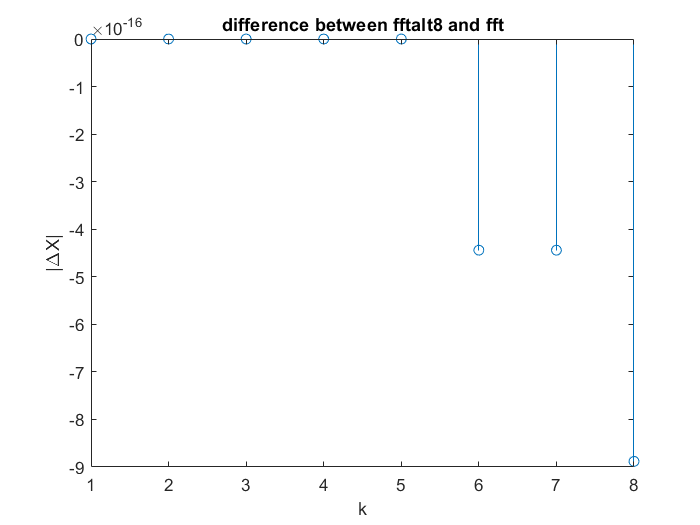

%Prob. 3(b)
x = [0,1,2,2,3,3,3,4];
X_alt = fftalt8(x);
X = fft(x);
dX = abs(X_alt)-abs(X);

figure
stem(dX)
title('difference between fftalt8 and fft')
xlabel('k')
ylabel('|\DeltaX|')

the difference between fftalt8 and fft is smaller than 10^-15

## 3. (c) 

%Prob. 3(c)
disp("fftalt8")

fftalt8


tic
fftalt8(x);
toc

Elapsed time is 0.009654 seconds.



disp("fftditr2")

fftditr2


tic
fftditr2(x);
toc

Elapsed time is 0.214758 seconds.


## **4. (b)**

v = 2


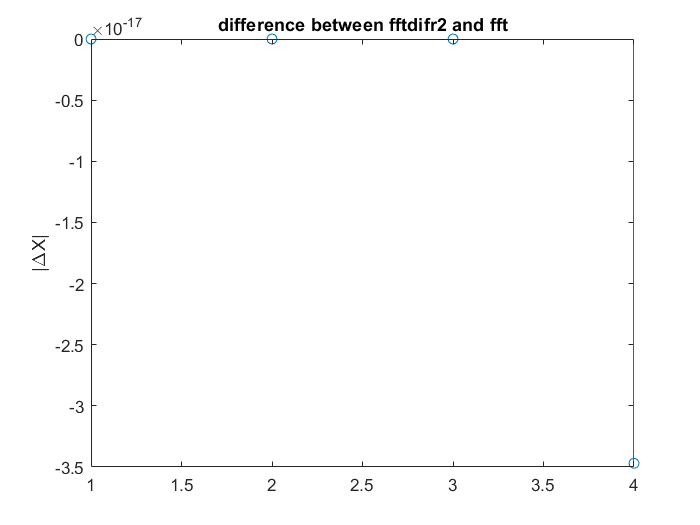

v = 3


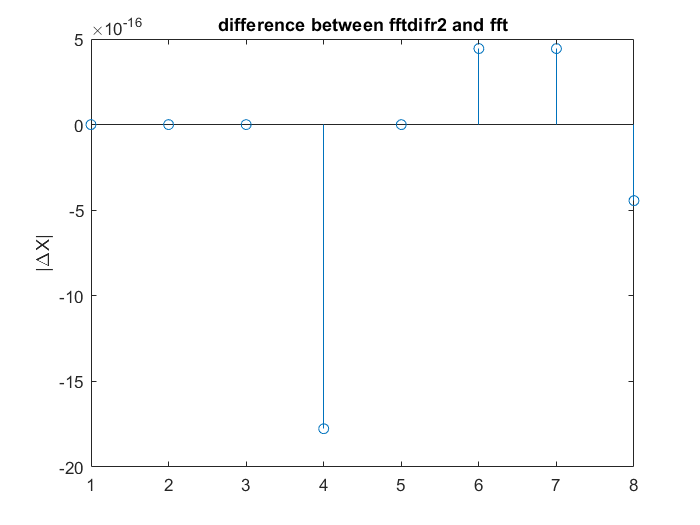

v = 4


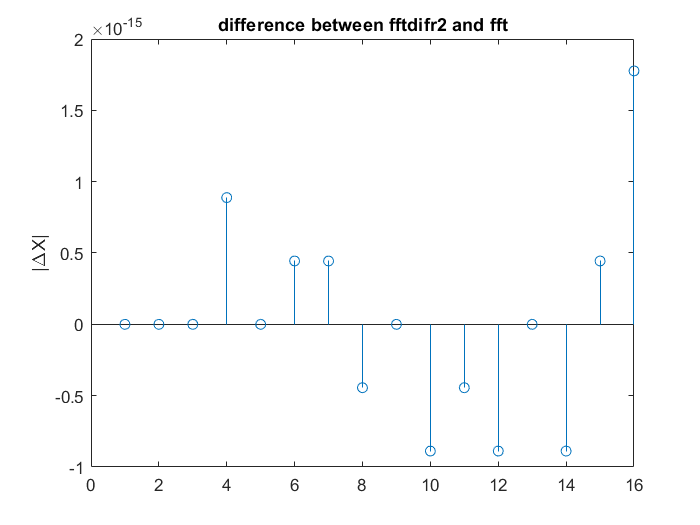

v = 5


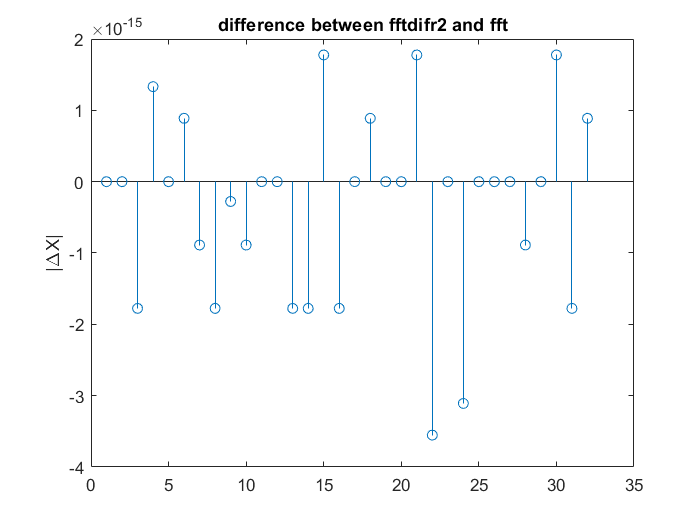

v = 6


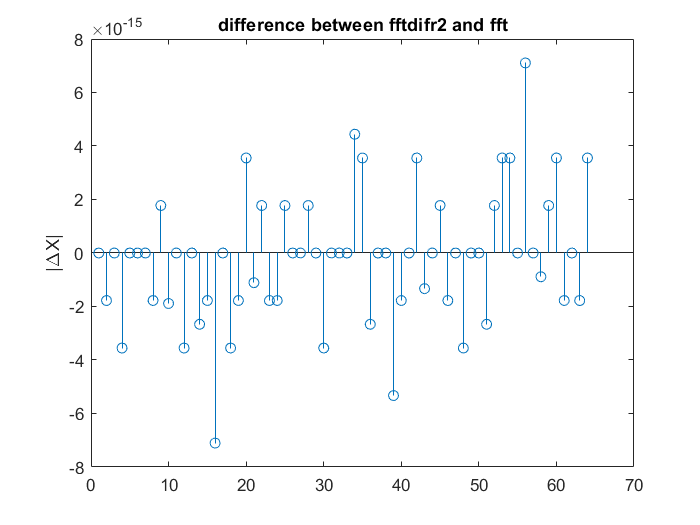

v = 7


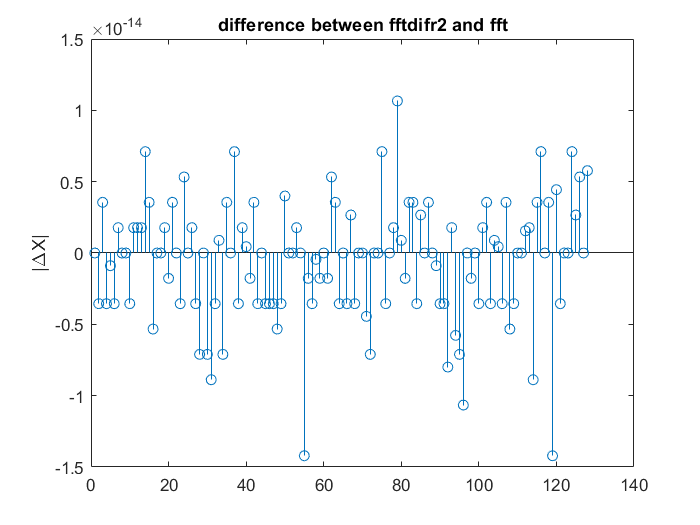

v = 8


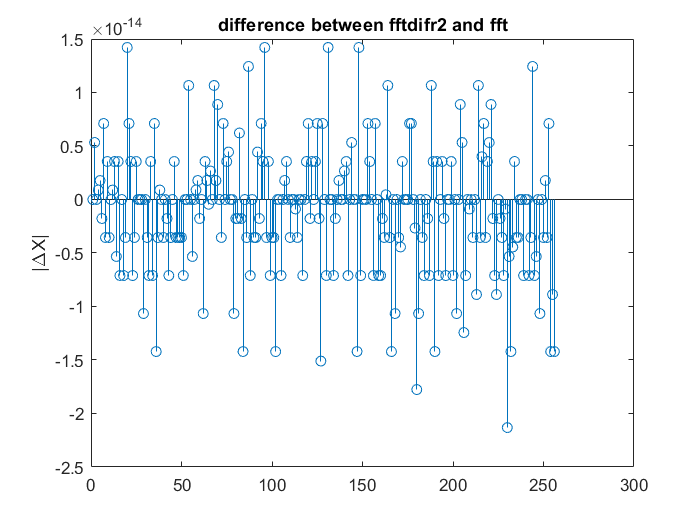

v = 9


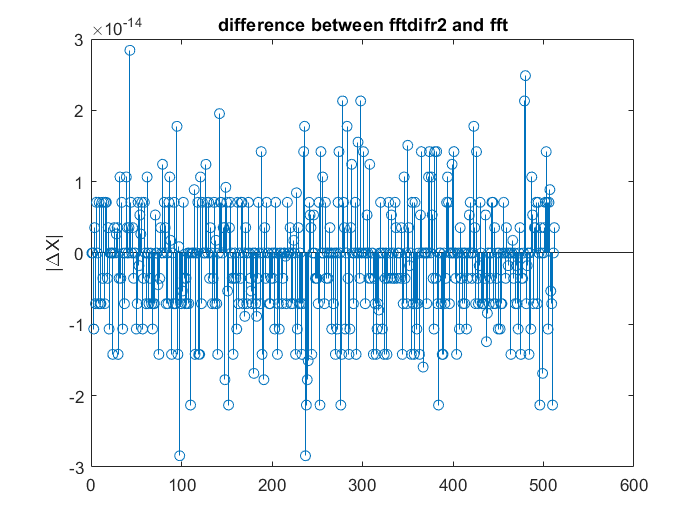

v = 10


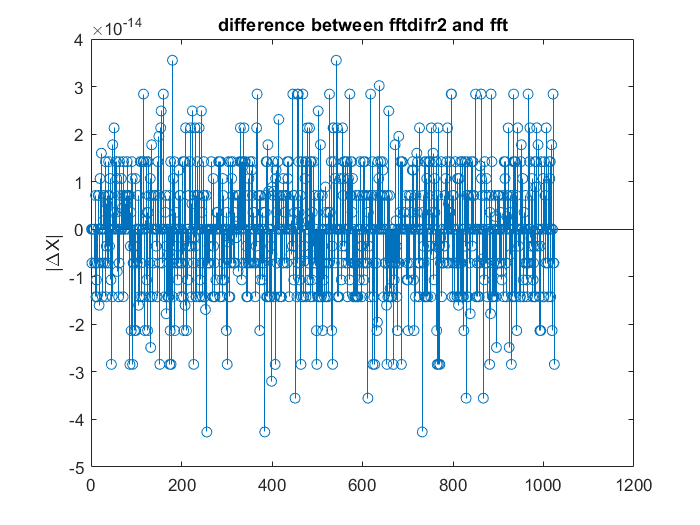

%Prob. 4(b)
for v = 2:10
    N = 2^v;
    x = randn(1,N) + 1j*randn(1,N);
    X = fft(x);
    X_dif = fftdifr2(x);
    dX = abs(X_dif)-abs(X);
    
    fprintf("v = %d\n", v);
    figure
    stem(dX)
    title('difference between fftdifr2 and fft')
    ylabel('|\DeltaX|')
end

## **5**

%Prob. 5(b)
h1 = [1,2,3,2,1];
h2 = [1,-2,3,3,-2,1];
h3 = [1,-5,0,5,-1];
h4 = [1,-3,-4,4,3,-1];
h5 = [1,2,3,-2,-1];
x=ones(1,10);
y1_lp = filterfirlp(h1,x);

Type I


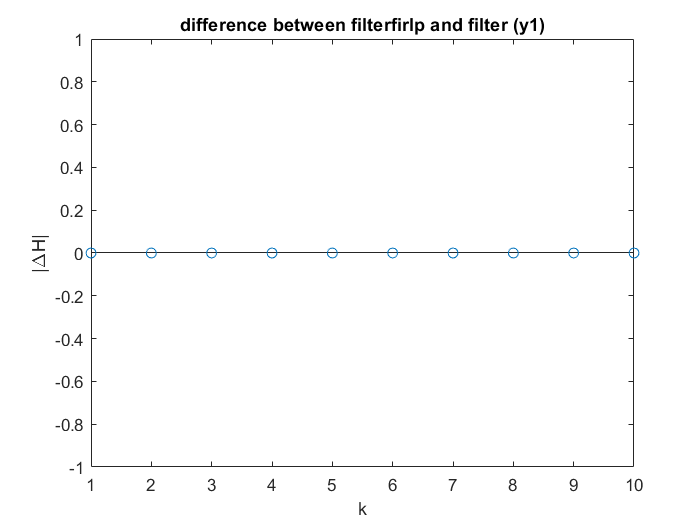

y1 = filter(h1,1,x);
dy1 = y1_lp - y1;

figure
stem(dy1)
title('difference between filterfirlp and filter (y1)')
xlabel('k')
ylabel('|\DeltaH|')


y2_lp = filterfirlp(h2,x);

Type II


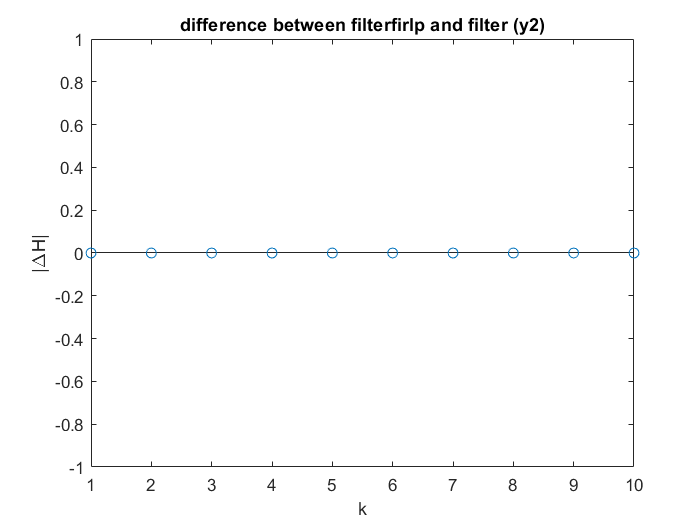

y2 = filter(h2,1,x);
dy2 = y2_lp - y2;

figure
stem(dy2)
title('difference between filterfirlp and filter (y2)')
xlabel('k')
ylabel('|\DeltaH|')


y3_lp = filterfirlp(h3,x);

Type III


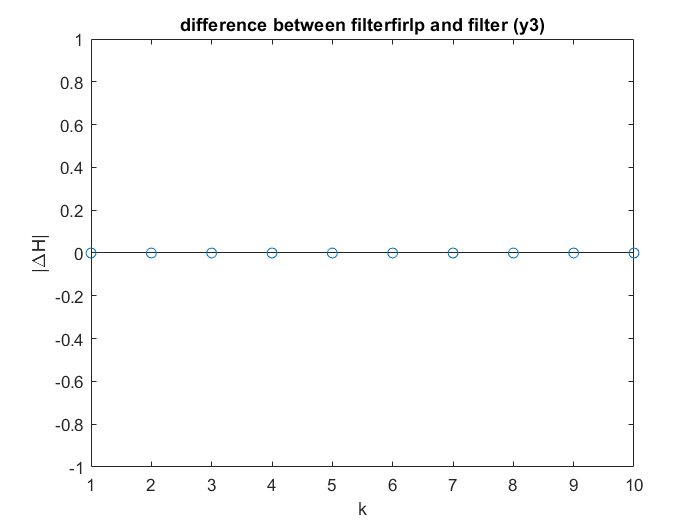

y3 = filter(h3,1,x);
dy3 = y3_lp - y3;

figure
stem(dy3)
title('difference between filterfirlp and filter (y3)')
xlabel('k')
ylabel('|\DeltaH|')


y4_lp = filterfirlp(h4,x);

Type IV


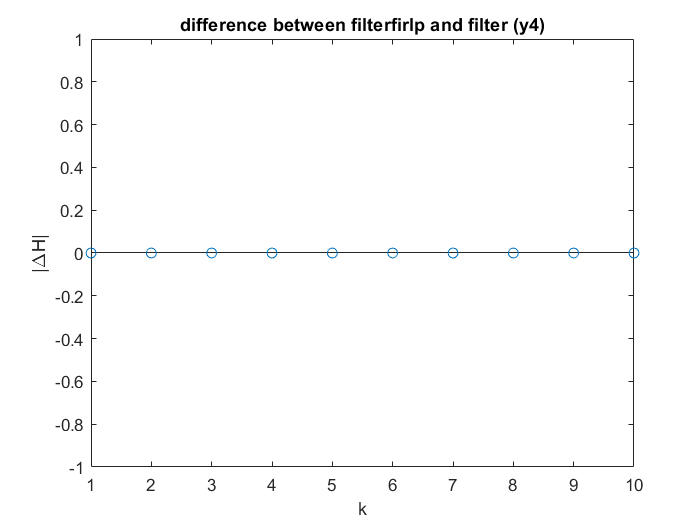

y4 = filter(h4,1,x);
dy4 = y4_lp - y4;

figure
stem(dy4)
title('difference between filterfirlp and filter (y4)')
xlabel('k')
ylabel('|\DeltaH|')


y5_lp = filterfirlp(h5,x);

Error


y5 = filter(h5,1,x);
dy5 = y5_lp - y5;

Matrix dimensions must agree.


figure
stem(dy5)
title('difference between filterfirlp and filter (y5)')
xlabel('k')
ylabel('|\DeltaH|')

## **6. (b)**

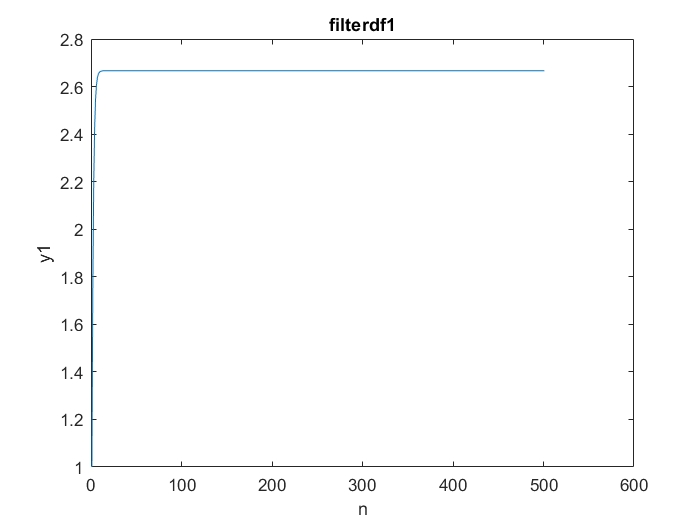

%Prob. 6(b)
n = 0:500;
x = (1/4).^n;
a = [1 -3/2 1/2];
b = 1;
y1 = filterdf1(b,a,x);
y2 = filterdf2(b,a,x);
dy = y1 - y2;

figure
plot(y1)
title('filterdf1')
xlabel('n')
ylabel('y1')

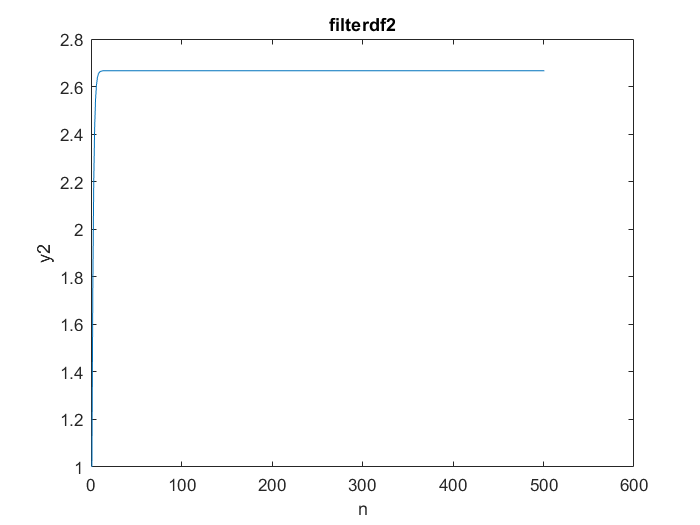


figure
plot(y2)
title('filterdf2')
xlabel('n')
ylabel('y2')

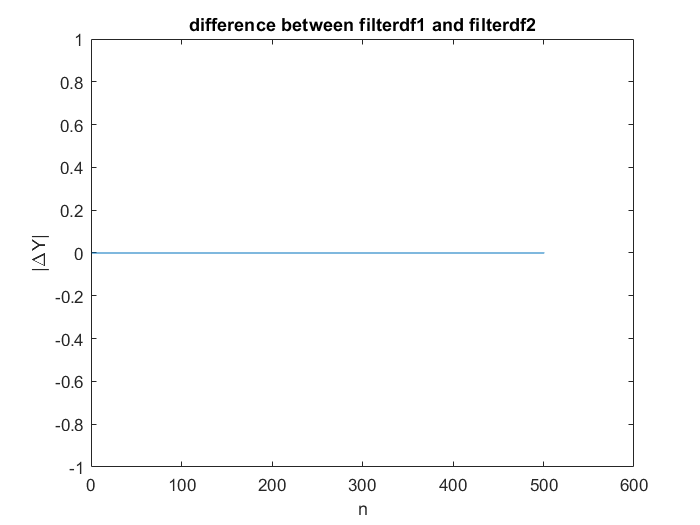


figure
plot(dy)
title('difference between filterdf1 and filterdf2')
xlabel('n')
ylabel('|\DeltaY|')

## **7**

%Prob. 7
b = [1 -2.61 2.75 -1.36 0.27];
a = [1 -1.05 0.91 -0.8 0.38]; 
[sos, G] = tf2sos(b,a)

sos =     1.0000   -1.4066    0.6260    1.0000   -1.3076    0.5305
    1.0000   -1.2034    0.4313    1.0000    0.2576    0.7163


G = 1

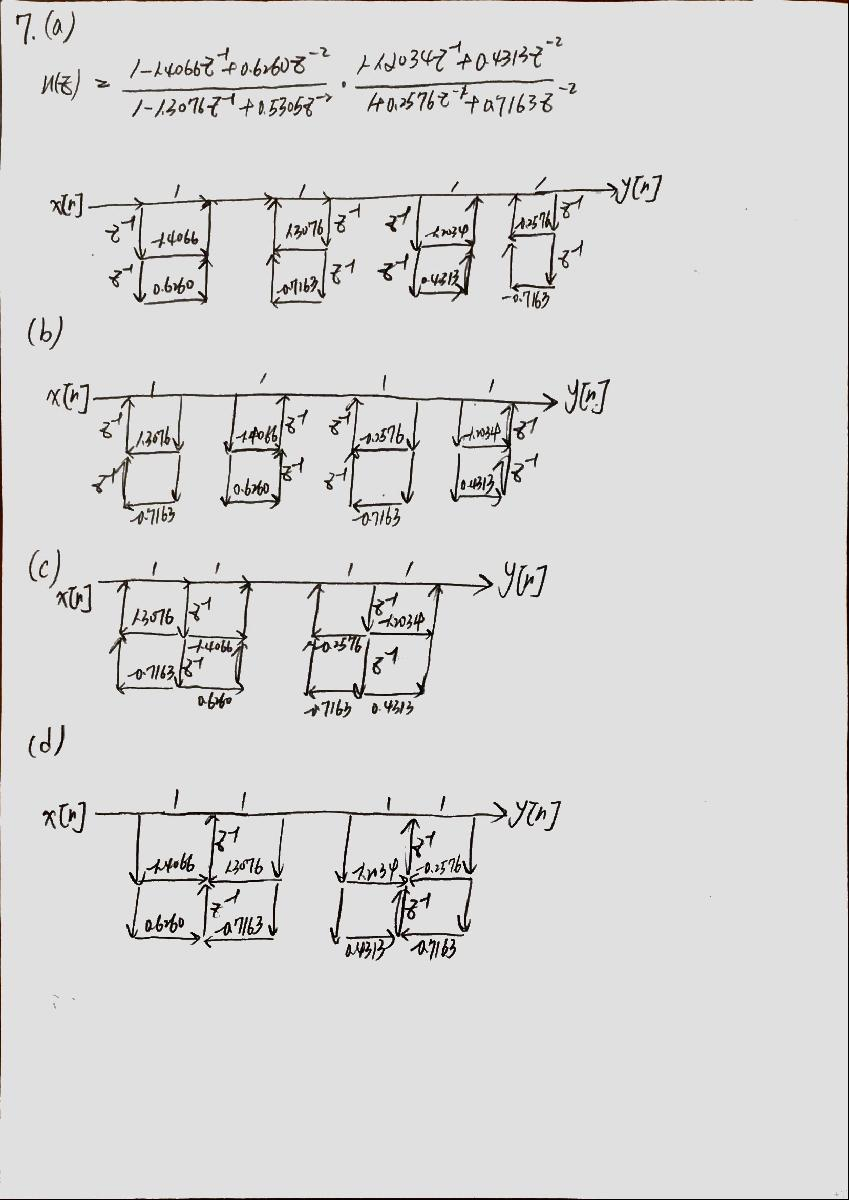

## **8. (b)**

%Prob. 8(b)
k = 0:32;
H = [1 1 1 0.5 zeros(1,26) 0.5 1 1] .* exp(-i*32*pi/33*k);
h = ifft(H);

[G,sos] = firdf2fs(h)

G =    1.0000 + 0.0000i
   2.0000 + 0.0000i
   2.0000 + 0.0000i
   1.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


sos =     1.0000         0         0    1.0000   -1.0000         0
   -0.9955    0.9955         0    1.0000   -1.9639    1.0000
    0.9819   -0.9819         0    1.0000   -1.8567    1.0000
   -0.9595    0.9595         0    1.0000   -1.6825    1.0000
    0.9970   -0.6681         0    1.0000   -1.4475    1.0000
    0.1169   -0.8768         0    1.0000   -1.1601    1.0000
    0.1670    0.8275         0    1.0000   -0.8308    1.0000
   -0.9942    0.3387         0    1.0000   -0.4715    1.0000
   -0.7372    0.7100         0    1.0000   -0.0952    1.0000
    0.0000   -0.9898         0    1.0000    0.2846    1.0000


by result we can get,


$$\frac{1}{1-z^{-1} }+\frac{-1\ldotp 991+1\ldotp 991z^{-1} }{1-1\ldotp 9639z^{-1} +z^{-2} }+\frac{1\ldotp 9638-1\ldotp 9638z^{-1} }{1-1\ldotp 8567z^{-1} +z^{-2} }+\frac{-0\ldotp 9595+0\ldotp 9595z^{-1} }{1-1\ldotp 6825z^{-1} +z^{-2} }$$
